clear
%loads a table that contains the information of both, multichannel
%and tungsten recordings. 
Table_DG_Aud = load('D:\Jazmin\MultichannelDataTanks\HIP\Table_DG_Aud.mat');
Table_DG_Sig = load('D:\Jazmin\MultichannelDataTanks\HIP\Table_DG_Sig.mat');
Table_CA1_Aud = load('D:\Jazmin\MultichannelDataTanks\HIP\CompleteSpikesCA1_Sig.mat'); %Dispait the name it has the Table_CA1_Aud
Table_CA1_Sig = load('D:\Jazmin\MultichannelDataTanks\HIP\Table_CA1_Sig.mat');

rangoY = [0 80];
rangoY_CSI = [0 40];

%SI CA1
figure
%Create histogram
scatter(Table_CA1_Aud.Table_CA1_Aud.SI1,Table_CA1_Aud.Table_CA1_Aud.SI2,'filled', 'MarkerFaceColor','#990033', 'MarkerFaceAlpha',.25,'MarkerEdgeAlpha',.25);
hold on
scatter(Table_CA1_Sig.Table_CA1_Sig.SI1,Table_CA1_Sig.Table_CA1_Sig.SI2,'filled', 'MarkerFaceColor','#990033', 'MarkerFaceAlpha',1);
xlim([-1 1]);
ylim([-1 1]);
title('SI CA1');
xlabel('SI F1');
ylabel('SI F2');

%Calculating the mean and error
SI_Mean = mean([Table_CA1_Aud.Table_CA1_Aud.SI1;Table_CA1_Aud.Table_CA1_Aud.SI2],"omitnan")

SI_Mean = 0.0481

SI_std = std([Table_CA1_Aud.Table_CA1_Aud.SI1;Table_CA1_Aud.Table_CA1_Aud.SI2],"omitnan");
err_SI = SI_std / sqrt((size([Table_CA1_Aud.Table_CA1_Aud.SI1;Table_CA1_Aud.Table_CA1_Aud.SI2],1))*2)

err_SI = 0.0144


SI_Mean_S = mean([Table_CA1_Sig.Table_CA1_Sig.SI1;Table_CA1_Sig.Table_CA1_Sig.SI2],"omitnan")

SI_Mean_S = 0.2578

SI_std_S = std([Table_CA1_Sig.Table_CA1_Sig.SI1;Table_CA1_Sig.Table_CA1_Sig.SI2],"omitnan");
err_SI_S = SI_std_S / sqrt((size([Table_CA1_Sig.Table_CA1_Sig.SI1;Table_CA1_Sig.Table_CA1_Sig.SI2],1))*2)

err_SI_S = 0.0261


CA1_Aud=size(Table_CA1_Aud.Table_CA1_Aud.SI1,1)

CA1_Aud = 63

CA1_Sig=size(Table_CA1_Sig.Table_CA1_Sig.SI1,1)

CA1_Sig = 21


[h p_SI_CA1] = ttest([Table_CA1_Aud.Table_CA1_Aud.SI1;Table_CA1_Aud.Table_CA1_Aud.SI2]) 

h = 1

p_SI_CA1 = 0.0196

[h p_SI_sig_CA1] = ttest([Table_CA1_Sig.Table_CA1_Sig.SI1;Table_CA1_Sig.Table_CA1_Sig.SI2]) 

h = 1

p_SI_sig_CA1 = 1.6951e-08

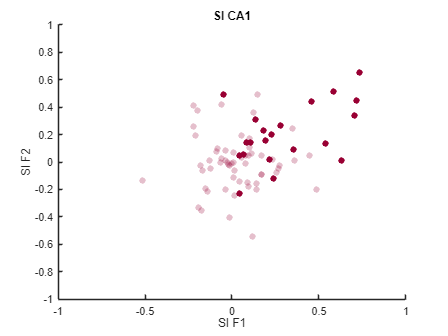


% [c_pvalues, c_alpha, h] = fwer_holmbonf(p_SI, 0.05);
% [c_pvalues, c_alpha, h] = fwer_holmbonf(p_SI_sig , 0.05);

%Save figure
cd 'D:\Jazmin\MultichannelDataTanks\HIP\SI'
saveas(gcf,'SI_CA1.pdf');
saveas(gcf,'SI_CA1.tif');
saveas(gcf,'SI_CA1.fig');
hold off

[h_kstest_SI,p_kstest_SI] = kstest([Table_CA1_Aud.Table_CA1_Aud.SI1;Table_CA1_Aud.Table_CA1_Aud.SI2])

h_kstest_SI = logical
   1


p_kstest_SI = 2.8806e-15

[h_kstest_SI_S,p_kstest_SI_S] = kstest([Table_CA1_Sig.Table_CA1_Sig.SI1;Table_CA1_Sig.Table_CA1_Sig.SI2])

h_kstest_SI_S = logical
   1


p_kstest_SI_S = 1.4992e-07

[h_ad_SI,p_ad_SI] = adtest([Table_CA1_Aud.Table_CA1_Aud.SI1;Table_CA1_Aud.Table_CA1_Aud.SI2])

h_ad_SI = logical
   1


p_ad_SI = 5.0000e-04

[h_ad_SI_S,p_ad_SI_S] = adtest([Table_CA1_Sig.Table_CA1_Sig.SI1;Table_CA1_Sig.Table_CA1_Sig.SI2])

h_ad_SI_S = logical
   1


p_ad_SI_S = 0.0478

%SI DG
figure
%Create histogram
scatter(Table_DG_Aud.Table_DG_Aud.SI1,Table_DG_Aud.Table_DG_Aud.SI2,'filled', 'MarkerFaceColor','#990033', 'MarkerFaceAlpha',.25,'MarkerEdgeAlpha',.25);
hold on
scatter(Table_DG_Sig.Table_DG_Sig.SI1,Table_DG_Sig.Table_DG_Sig.SI2,'filled', 'MarkerFaceColor','#990033', 'MarkerFaceAlpha',1);
xlim([-1 1]);
ylim([-1 1]);
title('SI DG');
xlabel('SI F1');
ylabel('SI F2');

%Calculating the mean and error
SI_Mean = mean([Table_DG_Aud.Table_DG_Aud.SI1;Table_DG_Aud.Table_DG_Aud.SI2],"omitnan")

SI_Mean = 0.1070

SI_std = std([Table_DG_Aud.Table_DG_Aud.SI1;Table_DG_Aud.Table_DG_Aud.SI2],"omitnan");
err_SI = SI_std / sqrt((size([Table_DG_Aud.Table_DG_Aud.SI1;Table_DG_Aud.Table_DG_Aud.SI2],1))*2)

err_SI = 0.0112


SI_Mean_S = mean([Table_DG_Sig.Table_DG_Sig.SI1;Table_DG_Sig.Table_DG_Sig.SI2],"omitnan")

SI_Mean_S = 0.3388

SI_std_S = std([Table_DG_Sig.Table_DG_Sig.SI1;Table_DG_Sig.Table_DG_Sig.SI2],"omitnan");
err_SI_S = SI_std_S / sqrt((size([Table_DG_Sig.Table_DG_Sig.SI1;Table_DG_Sig.Table_DG_Sig.SI2],1))*2)

err_SI_S = 0.0279


DG_Aud=size(Table_DG_Aud.Table_DG_Aud.SI1,1)

DG_Aud = 107

DG_Sig=size(Table_DG_Sig.Table_DG_Sig.SI1,1)

DG_Sig = 22


[h p_SI_DG] = ttest([Table_DG_Aud.Table_DG_Aud.SI1;Table_DG_Aud.Table_DG_Aud.SI2]) 

h = 1

p_SI_DG = 1.1228e-10

[h p_SI_sig_DG] = ttest([Table_DG_Sig.Table_DG_Sig.SI1;Table_DG_Sig.Table_DG_Sig.SI2]) 

h = 1

p_SI_sig_DG = 6.7984e-11

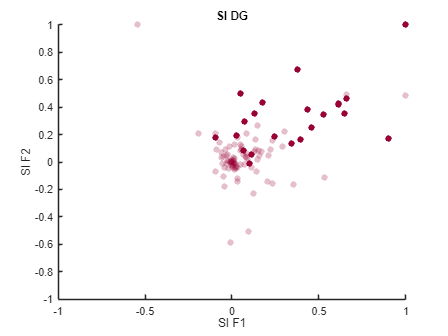


% [c_pvalues, c_alpha, h] = fwer_holmbonf(p_SI, 0.05);
% [c_pvalues, c_alpha, h] = fwer_holmbonf(p_SI_sig , 0.05);

%Save figure
cd 'D:\Jazmin\MultichannelDataTanks\HIP\SI'
saveas(gcf,'SI_DG.pdf');
saveas(gcf,'SI_DG.tif');
saveas(gcf,'SI_DG.fig');
hold off

[h_kstest_SI,p_kstest_SI] = kstest([Table_DG_Aud.Table_DG_Aud.SI1;Table_DG_Aud.Table_DG_Aud.SI2])

h_kstest_SI = logical
   1


p_kstest_SI = 8.3593e-32

[h_kstest_SI_S,p_kstest_SI_S] = kstest([Table_DG_Sig.Table_DG_Sig.SI1;Table_DG_Sig.Table_DG_Sig.SI2])

h_kstest_SI_S = logical
   1


p_kstest_SI_S = 2.2336e-09

[h_ad_SI,p_ad_SI] = adtest([Table_DG_Aud.Table_DG_Aud.SI1;Table_DG_Aud.Table_DG_Aud.SI2])

h_ad_SI = logical
   1


p_ad_SI = 5.0000e-04

[h_ad_SI_S,p_ad_SI_S] = adtest([Table_DG_Sig.Table_DG_Sig.SI1;Table_DG_Sig.Table_DG_Sig.SI2])

h_ad_SI_S = logical
   0


p_ad_SI_S = 0.0569

% CSI SignificantSSA
figure
%Create histogram
histogram(Table_CA1_Aud.Table_CA1_Aud.CSI,'BinWidth',0.1, 'FaceColor','#990033','FaceAlpha',.25,'EdgeAlpha',.25);
hold on
histogram(Table_CA1_Sig.Table_CA1_Sig.CSI,'BinWidth',0.1, 'FaceColor','#990033','FaceAlpha',1,'EdgeAlpha',1);
xlim([-1 1]);
ylim(rangoY_CSI);
xline(0,'LineWidth',2);
title('CSI CA1');
xlabel('CSI index');
ylabel('repetitions');

%Calculating the mean and error
CSI_Mean = median(Table_CA1_Aud.Table_CA1_Aud.CSI,"omitnan")

CSI_Mean = 0.0188

CSI_std = std(Table_CA1_Aud.Table_CA1_Aud.CSI,"omitnan");
err_CSI = CSI_std ./ sqrt(size(Table_CA1_Aud.Table_CA1_Aud.CSI))

err_CSI =     0.0220    0.1749


xline(CSI_Mean,'LineWidth',2);

CSI_Mean_S = median(Table_CA1_Sig.Table_CA1_Sig.CSI,"omitnan")

CSI_Mean_S = 0.2128

CSI_std_S = std(Table_CA1_Sig.Table_CA1_Sig.CSI,"omitnan");
err_CSI_S = CSI_std_S ./ sqrt(size(Table_CA1_Sig.Table_CA1_Sig.CSI))

err_CSI_S =     0.0433    0.1985


xline(CSI_Mean_S,'LineWidth',2.5);


[h p_CSI_CA1] = ttest(Table_CA1_Aud.Table_CA1_Aud.CSI) 

h = 1

p_CSI_CA1 = 0.0209

[h p_CSI_sig_CA1] = ttest(Table_CA1_Sig.Table_CA1_Sig.CSI) 

h = 1

p_CSI_sig_CA1 = 1.0072e-05

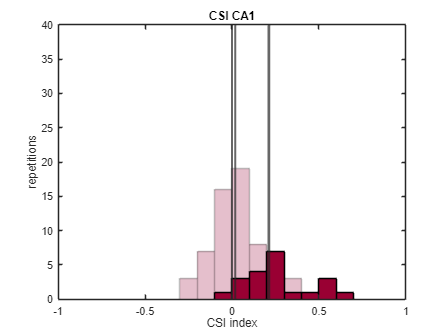


% [c_pvalues, c_alpha, h] = fwer_holmbonf(p_CSI, 0.05);
% [c_pvalues, c_alpha, h] = fwer_holmbonf(p_CSI_sig , 0.05);

% [p_CSI h] = signrank(NormalizedIndexesTable.CSI(SIscatterIndx,1)) 
% [p_CSI_sig h] = signrank(NormalizedIndexesTable.CSI(SignificantSSA,1)) 

%Save figure
cd 'D:\Jazmin\MultichannelDataTanks\HIP\CSI';
saveas(gcf,'CSI_CA1.pdf');
saveas(gcf,'CSI_CA1.tif');
saveas(gcf,'CSI_CA1.fig');
hold off


[h_kstest_CSI,p_kstest_CSI] = kstest(Table_CA1_Aud.Table_CA1_Aud.CSI)

h_kstest_CSI = logical
   1


p_kstest_CSI = 1.2188e-09

[h_kstest_CSI_S,p_kstest_CSI_S] = kstest(Table_CA1_Sig.Table_CA1_Sig.CSI)

h_kstest_CSI_S = logical
   1


p_kstest_CSI_S = 8.5628e-05

[h_ad_CSI,p_ad_CSI] = adtest(Table_CA1_Aud.Table_CA1_Aud.CSI)

h_ad_CSI = logical
   1


p_ad_CSI = 5.0000e-04

[h_ad_CSI_S,p_ad_CSI_S] = adtest(Table_CA1_Sig.Table_CA1_Sig.CSI)

h_ad_CSI_S = logical
   0


p_ad_CSI_S = 0.1095

% CSI SignificantSSA
figure
%Create histogram
histogram(Table_DG_Aud.Table_DG_Aud.CSI,'BinWidth',0.1, 'FaceColor','#990033','FaceAlpha',.25,'EdgeAlpha',.25);
hold on
histogram(Table_DG_Sig.Table_DG_Sig.CSI,'BinWidth',0.1, 'FaceColor','#990033','FaceAlpha',1,'EdgeAlpha',1);
xlim([-1 1]);
ylim(rangoY_CSI);
xline(0,'LineWidth',2);
title('CSI DG');
xlabel('CSI index');
ylabel('repetitions');

%Calculating the mean and error
CSI_Mean = median(Table_DG_Aud.Table_DG_Aud.CSI,"omitnan")

CSI_Mean = 0.0466

CSI_std = std(Table_DG_Aud.Table_DG_Aud.CSI,"omitnan");
err_CSI = CSI_std ./ sqrt(size(Table_DG_Aud.Table_DG_Aud.CSI))

err_CSI =     0.0176    0.1816


xline(CSI_Mean,'LineWidth',2);

CSI_Mean_S = median(Table_DG_Sig.Table_DG_Sig.CSI,"omitnan")

CSI_Mean_S = 0.2714

CSI_std_S = std(Table_DG_Sig.Table_DG_Sig.CSI,"omitnan");
err_CSI_S = CSI_std_S ./ sqrt(size(Table_DG_Sig.Table_DG_Sig.CSI))

err_CSI_S =     0.0483    0.2265


xline(CSI_Mean_S,'LineWidth',2.5);


[h p_CSI_DG] = ttest(Table_DG_Aud.Table_DG_Aud.CSI) 

h = 1

p_CSI_DG = 6.9495e-09

[h p_CSI_sig_DG] = ttest(Table_DG_Sig.Table_DG_Sig.CSI) 

h = 1

p_CSI_sig_DG = 9.0347e-07

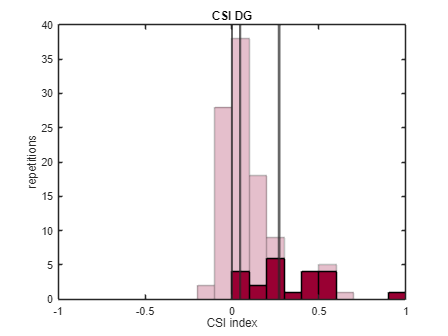


% [c_pvalues, c_alpha, h] = fwer_holmbonf(p_CSI, 0.05);
% [c_pvalues, c_alpha, h] = fwer_holmbonf(p_CSI_sig , 0.05);

% [p_CSI h] = signrank(NormalizedIndexesTable.CSI(SIscatterIndx,1)) 
% [p_CSI_sig h] = signrank(NormalizedIndexesTable.CSI(SignificantSSA,1)) 

%Save figure
cd 'D:\Jazmin\MultichannelDataTanks\HIP\CSI';
saveas(gcf,'CSI_DG.pdf');
saveas(gcf,'CSI_DG.tif');
saveas(gcf,'CSI_DG.fig');
hold off


[h_kstest_CSI,p_kstest_CSI] = kstest(Table_DG_Aud.Table_DG_Aud.CSI)

h_kstest_CSI = logical
   1


p_kstest_CSI = 1.2705e-19

[h_kstest_CSI_S,p_kstest_CSI_S] = kstest(Table_DG_Sig.Table_DG_Sig.CSI)

h_kstest_CSI_S = logical
   1


p_kstest_CSI_S = 5.2142e-06

[h_ad_CSI,p_ad_CSI] = adtest(Table_DG_Aud.Table_DG_Aud.CSI)

h_ad_CSI = logical
   1


p_ad_CSI = 5.0000e-04

[h_ad_CSI_S,p_ad_CSI_S] = adtest(Table_DG_Sig.Table_DG_Sig.CSI)

h_ad_CSI_S = logical
   0


p_ad_CSI_S = 0.1665

pValues = [p_SI_DG; p_SI_sig_DG; p_SI_CA1; p_SI_sig_CA1; p_CSI_DG; p_CSI_sig_DG; p_CSI_CA1; p_CSI_sig_CA1];

m = length(pValues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
correctedPValues = pValues * m;

% Display results
table(pValues, correctedPValues, 'VariableNames', {'pValue', 'Bonfe_Cor_pValue'})

ans = 8×2 table
      pValue      Bonfe_Cor_pValue
    __________    ________________

    1.1228e-10       8.9824e-10   
    6.7984e-11       5.4387e-10   
      0.019648          0.15718   
    1.6951e-08       1.3561e-07   
    6.9495e-09       5.5596e-08   
    9.0347e-07       7.2277e-06   
      0.020918          0.16734   
    1.0072e-05       8.0575e-05   


% iMM CA1
iMMcasc_CA1 = cat(1,Table_CA1_Aud.Table_CA1_Aud.iMM1ca,Table_CA1_Aud.Table_CA1_Aud.iMM2cd);
figure
hold on
iMMcasc_S_CA1 = cat(1,Table_CA1_Sig.Table_CA1_Sig.iMM1ca,Table_CA1_Sig.Table_CA1_Sig.iMM2cd);
%Create histogram
hiMM_CA1_Aud=histogram(iMMcasc_CA1,'BinWidth',0.1,'FaceColor','#EA005F','FaceAlpha',.25,'EdgeAlpha',.25);
hiMM_CA1_Sig=histogram(iMMcasc_S_CA1,'BinWidth',0.1,'FaceColor','#EA005F','FaceAlpha',1,'EdgeAlpha',1);
xlim([-1 1]);
ylim([rangoY]);
xline(0,'LineWidth',2);
title('iMM CA1');
xlabel('iMM index');
ylabel('repetitions');

%Calculating the mean and error
iMMcasc_Mean = nanmedian(iMMcasc_CA1)

iMMcasc_Mean = 0.0156

iMMcasc_std = nanstd(iMMcasc_CA1);
err_iMMcasc = iMMcasc_std ./ sqrt(size(iMMcasc_CA1,1))

err_iMMcasc = 0.0219

xline(iMMcasc_Mean,'LineWidth',2);

iMMcasc_Mean_S = nanmedian(iMMcasc_S_CA1)

iMMcasc_Mean_S = 0.2299

iMMcasc_std_S = nanstd(iMMcasc_S_CA1);
err_iMMcasc_S = iMMcasc_std_S ./ sqrt(size(iMMcasc_S_CA1,1))

err_iMMcasc_S = 0.0383

xline(iMMcasc_Mean_S,'LineWidth',2.5);

[h p_iMM_CA1] = ttest(iMMcasc_CA1)

h = 1

p_iMM_CA1 = 0.0068

[h p_iMM_sig_CA1 ] = ttest(iMMcasc_S_CA1)

h = 1

p_iMM_sig_CA1 = 9.3531e-09

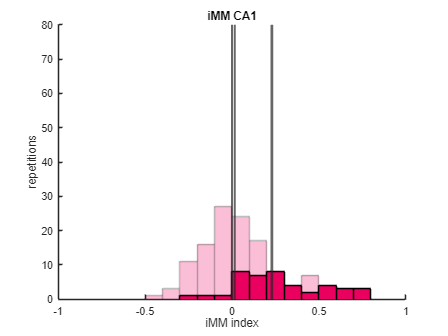


% [c_pvalues, c_alpha, h] = fwer_holmbonf(p_iMM, 0.05);
% [c_pvalues, c_alpha, h] = fwer_holmbonf(p_iMM_sig , 0.05);

% [p_iMM_sig h] = signrank(iMMcasc)
% [p_iMM_sig h] = signrank(iMMcasc_sig)

%Save figure
PathiMM = 'D:\Jazmin\MultichannelDataTanks\HIP\iMM';
cd (PathiMM);
saveas(gcf,'iMM_CA1.pdf');
saveas(gcf,'iMM_CA1.tif');
saveas(gcf,'iMM_CA1.fig');
hold off

[h_kstest_iMM,p_kstest_iMM] = kstest(iMMcasc_CA1)

h_kstest_iMM = logical
   1


p_kstest_iMM = 1.2300e-14

[h_kstest_iMM_S,p_kstest_iMM_S] = kstest(iMMcasc_S_CA1)

h_kstest_iMM_S = logical
   1


p_kstest_iMM_S = 1.5203e-07

[h_ad_iMM,p_ad_iMM] = adtest(iMMcasc_CA1)

h_ad_iMM = logical
   1


p_ad_iMM = 5.0000e-04

[h_ad_iMM_S,p_ad_iMM_S] = adtest(iMMcasc_S_CA1)

h_ad_iMM_S = logical
   0


p_ad_iMM_S = 0.0781

% iMM
iMMcasc_DG = cat(1,Table_DG_Aud.Table_DG_Aud.iMM1ca,Table_DG_Aud.Table_DG_Aud.iMM2cd);
figure
hold on
iMMcasc_S_DG = cat(1,Table_DG_Sig.Table_DG_Sig.iMM1ca,Table_DG_Sig.Table_DG_Sig.iMM2cd);
%Create histogram
hiMM_DG_Aud=histogram(iMMcasc_DG,'BinWidth',0.1,'FaceColor','#EA005F','FaceAlpha',.25,'EdgeAlpha',.25);
hiMM_DG_Sig=histogram(iMMcasc_S_DG,'BinWidth',0.1,'FaceColor','#EA005F','FaceAlpha',1,'EdgeAlpha',1);
xlim([-1 1]);
ylim([rangoY]);
xline(0,'LineWidth',2);
title('iMM DG');
xlabel('iMM index');
ylabel('repetitions');

%Calculating the mean and error
iMMcasc_Mean = nanmedian(iMMcasc_DG)

iMMcasc_Mean = 0.0525

iMMcasc_std = nanstd(iMMcasc_DG);
err_iMMcasc = iMMcasc_std ./ sqrt(size(iMMcasc_DG,1))

err_iMMcasc = 0.0156

xline(iMMcasc_Mean,'LineWidth',2);

iMMcasc_Mean_S = nanmedian(iMMcasc_S_DG)

iMMcasc_Mean_S = 0.3366

iMMcasc_std_S = nanstd(iMMcasc_S_DG);
err_iMMcasc_S = iMMcasc_std_S ./ sqrt(size(iMMcasc_S_DG,1))

err_iMMcasc_S = 0.0387

xline(iMMcasc_Mean_S,'LineWidth',2.5);

[h p_iMM_DG] = ttest(iMMcasc_DG)

h = 1

p_iMM_DG = 6.8304e-12

[h p_iMM_sig_DG ] = ttest(iMMcasc_S_DG)

h = 1

p_iMM_sig_DG = 1.3659e-11

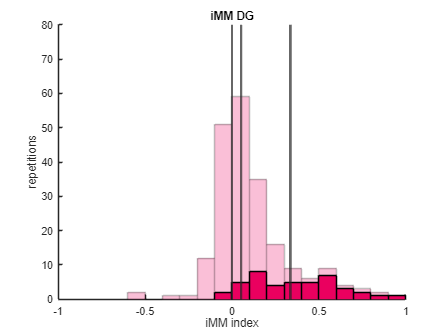


% [c_pvalues, c_alpha, h] = fwer_holmbonf(p_iMM, 0.05);
% [c_pvalues, c_alpha, h] = fwer_holmbonf(p_iMM_sig , 0.05);
% [p_iMM_sig h] = signrank(iMMcasc)
% [p_iMM_sig h] = signrank(iMMcasc_sig)

%Save figure
PathiMM = 'D:\Jazmin\MultichannelDataTanks\HIP\iMM';
cd (PathiMM);
saveas(gcf,'iMM_DG.pdf');
saveas(gcf,'iMM_DG.tif');
saveas(gcf,'iMM_DG.fig');
hold off

[h_kstest_iMM,p_kstest_iMM] = kstest(iMMcasc_DG)

h_kstest_iMM = logical
   1


p_kstest_iMM = 2.1191e-31

[h_kstest_iMM_S,p_kstest_iMM_S] = kstest(iMMcasc_S_DG)

h_kstest_iMM_S = logical
   1


p_kstest_iMM_S = 3.8199e-09

[h_ad_iMM,p_ad_iMM] = adtest(iMMcasc_DG)

h_ad_iMM = logical
   1


p_ad_iMM = 5.0000e-04

[h_ad_iMM_S,p_ad_iMM_S] = adtest(iMMcasc_S_DG)

h_ad_iMM_S = logical
   0


p_ad_iMM_S = 0.2797

% iPE CA1 SignificantSSA
iPEcasc_CA1 = cat(1,Table_CA1_Aud.Table_CA1_Aud.iPE1ca,Table_CA1_Aud.Table_CA1_Aud.iPE2cd);
iPEcasc_S_CA1 = cat(1,Table_CA1_Sig.Table_CA1_Sig.iPE1ca,Table_CA1_Sig.Table_CA1_Sig.iPE2cd);
figure
%Create histogram
hiPE_CA1_Aud = histogram(iPEcasc_CA1,'BinWidth',0.1,'FaceColor','#FF6600','FaceAlpha',.25,'EdgeAlpha',.25);
hold on
hiPE_CA1_Sig = histogram(iPEcasc_S_CA1,'BinWidth',0.1,'FaceColor','#FF6600','FaceAlpha',1,'EdgeAlpha',1);
xlim([-1 1]);
ylim([rangoY]);
xline(0,'LineWidth',2);
title('iPE CA1');
xlabel('iPE index');
ylabel('repetitions');

%Calculating the mean and error
iPEcasc_Mean = nanmedian(iPEcasc_CA1)

iPEcasc_Mean = 0.0386

iPEcasc_std = nanstd(iPEcasc_CA1);
err_iPEcasc = iPEcasc_std ./ sqrt(size(iPEcasc_CA1,1))

err_iPEcasc = 0.0257

xline(iPEcasc_Mean,'LineWidth',2);

iPEcasc_Mean_S = nanmedian(iPEcasc_S_CA1)

iPEcasc_Mean_S = 0.2030

iPEcasc_std_S = nanstd(iPEcasc_S_CA1);
err_iPEcasc_S = iPEcasc_std_S ./ sqrt(size(iPEcasc_S_CA1,1))

err_iPEcasc_S = 0.0417

xline(iPEcasc_Mean_S,'LineWidth',2.5);

[h p_iPE_CA1] = ttest(iPEcasc_CA1)

h = 1

p_iPE_CA1 = 0.0073

[h p_iPE_sig_CA1] = ttest(iPEcasc_S_CA1)

h = 1

p_iPE_sig_CA1 = 2.9804e-05

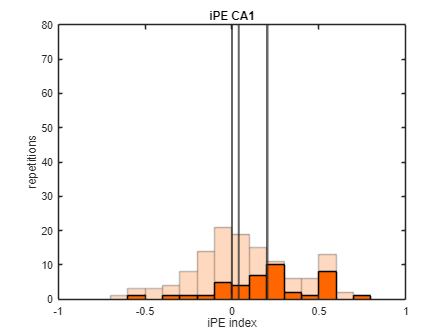


% [c_pvalues, c_alpha, h] = fwer_holmbonf(p_iPE, 0.05);
% [c_pvalues, c_alpha, h] = fwer_holmbonf(p_iPE_sig , 0.05);
% [p_iPE h] = signrank(iPEcasc)
% [p_iPE_sig h] = signrank(iPEcasc_sig)
%Save figure
cd 'D:\Jazmin\MultichannelDataTanks\HIP\iPE';
saveas(gcf,'iPE_CA1.pdf');
saveas(gcf,'iPE_CA1.tif');
saveas(gcf,'iPE_CA1.fig');
hold off

[h_kstest_iPE,p_kstest_iPE] = kstest(iPEcasc_CA1)

h_kstest_iPE = logical
   1


p_kstest_iPE = 5.1515e-11

[h_kstest_iPE_S,p_kstest_iPE_S] = kstest(iPEcasc_S_CA1)

h_kstest_iPE_S = logical
   1


p_kstest_iPE_S = 8.3752e-06

[h_ad_iPE,p_ad_iPE] = adtest(iPEcasc_CA1)

h_ad_iPE = logical
   0


p_ad_iPE = 0.1054

[h_ad_iPE_S,p_ad_iPE_S] = adtest(iPEcasc_S_CA1)

h_ad_iPE_S = logical
   0


p_ad_iPE_S = 0.1925

% iPE DG SignificantSSA
iPEcasc_DG = cat(1,Table_DG_Aud.Table_DG_Aud.iPE1ca,Table_DG_Aud.Table_DG_Aud.iPE2cd);
iPEcasc_S_DG = cat(1,Table_DG_Sig.Table_DG_Sig.iPE1ca,Table_DG_Sig.Table_DG_Sig.iPE2cd);
figure
%Create histogram
hiPE_DG_Aud = histogram(iPEcasc_DG,'BinWidth',0.1,'FaceColor','#FF6600','FaceAlpha',.25,'EdgeAlpha',.25);
hold on
hiPE_DG_Sig = histogram(iPEcasc_S_DG,'BinWidth',0.1,'FaceColor','#FF6600','FaceAlpha',1,'EdgeAlpha',1);
xlim([-1 1]);
ylim([rangoY]);
xline(0,'LineWidth',2);
title('iPE DG');
xlabel('iPE index');
ylabel('repetitions');

%Calculating the mean and error
iPEcasc_Mean = nanmedian(iPEcasc_DG)

iPEcasc_Mean = 0.0438

iPEcasc_std = nanstd(iPEcasc_DG);
err_iPEcasc = iPEcasc_std ./ sqrt(size(iPEcasc_DG,1))

err_iPEcasc = 0.0163

xline(iPEcasc_Mean,'LineWidth',2);

iPEcasc_Mean_S = nanmedian(iPEcasc_S_DG)

iPEcasc_Mean_S = 0.3032

iPEcasc_std_S = nanstd(iPEcasc_S_DG);
err_iPEcasc_S = iPEcasc_std_S ./ sqrt(size(iPEcasc_S_DG,1))

err_iPEcasc_S = 0.0471

xline(iPEcasc_Mean_S,'LineWidth',2.5);

[h p_iPE_DG] = ttest(iPEcasc_DG)

h = 1

p_iPE_DG = 3.0084e-09

[h p_iPE_sig_DG] = ttest(iPEcasc_S_DG)

h = 1

p_iPE_sig_DG = 3.0922e-06

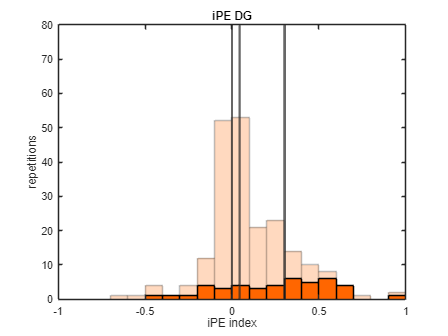


% [c_pvalues, c_alpha, h] = fwer_holmbonf(p_iPE, 0.05);
% [c_pvalues, c_alpha, h] = fwer_holmbonf(p_iPE_sig , 0.05);

% [p_iPE h] = signrank(iPEcasc)
% [p_iPE_sig h] = signrank(iPEcasc_sig)
%Save figure
cd 'D:\Jazmin\MultichannelDataTanks\HIP\iPE';
saveas(gcf,'iPE_DG.pdf');
saveas(gcf,'iPE_DG.tif');
saveas(gcf,'iPE_DG.fig');
hold off

[h_kstest_iPE,p_kstest_iPE] = kstest(iPEcasc_DG)

h_kstest_iPE = logical
   1


p_kstest_iPE = 5.8631e-27

[h_kstest_iPE_S,p_kstest_iPE_S] = kstest(iPEcasc_S_DG)

h_kstest_iPE_S = logical
   1


p_kstest_iPE_S = 2.1422e-05

[h_ad_iPE,p_ad_iPE] = adtest(iPEcasc_DG)

h_ad_iPE = logical
   1


p_ad_iPE = 5.0000e-04

[h_ad_iPE_S,p_ad_iPE_S] = adtest(iPEcasc_S_DG)

h_ad_iPE_S = logical
   0


p_ad_iPE_S = 0.3340

% iRS CA1
iRScasc_CA1 = cat(1,Table_CA1_Aud.Table_CA1_Aud.iRS1ca,Table_CA1_Aud.Table_CA1_Aud.iRS2cd);
iRScasc_S_CA1 = cat(1,Table_CA1_Sig.Table_CA1_Sig.iRS1ca,Table_CA1_Sig.Table_CA1_Sig.iRS2cd);
figure
%Create histogram
hiRS_CA1_Aud = histogram(iRScasc_CA1,'BinWidth',0.1,'FaceColor','#0099CC','FaceAlpha',.25,'EdgeAlpha',.25);
hold on
hiRS_CA1_Sig = histogram(iRScasc_S_CA1,'BinWidth',0.1,'FaceColor','#0099CC','FaceAlpha',1,'EdgeAlpha',1);
xlim([-1 1]);
ylim([rangoY]);
xline(0,'LineWidth',2);
title('iRS CA1');
xlabel('iRS index');
ylabel('repetitions');

%Calculating the mean and error
iRScasc_Mean = nanmedian(iRScasc_CA1)

iRScasc_Mean = -0.0014

iRScasc_std = nanstd(iRScasc_CA1);
err_iRScasc = iRScasc_std ./ sqrt(size(iRScasc_CA1,1))

err_iRScasc = 0.0197

xline(iRScasc_Mean,'LineWidth',2.5);

iRScasc_Mean_S = nanmedian(iRScasc_S_CA1)

iRScasc_Mean_S = 0.0211

iRScasc_std_S = nanstd(iRScasc_S_CA1);
err_iRScasc_S = iRScasc_std_S ./ sqrt(size(iRScasc_S_CA1,1))

err_iRScasc_S = 0.0355

xline(iRScasc_Mean_S,'LineWidth',2.5);

[h p_iRS_CA1] = ttest(iRScasc_CA1)

h = 0

p_iRS_CA1 = 0.6179

[h p_iRS_sig_CA1] = ttest(iRScasc_S_CA1)

h = 1

p_iRS_sig_CA1 = 0.0314

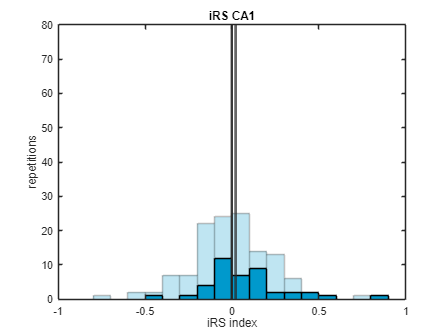


% [c_pvalues, c_alpha, h] = fwer_holmbonf(p_iRS, 0.05);
% [c_pvalues, c_alpha, h] = fwer_holmbonf(p_iRS_sig , 0.05);
% [p_iRS_sig h] = signrank(iRScasc)
% [p_iRS h] = signrank(iRScasc_S)

%Save figure
cd 'D:\Jazmin\MultichannelDataTanks\HIP\iRS';
saveas(gcf,'iRS_CA1.pdf');
saveas(gcf,'iRS_CA1.tif');
saveas(gcf,'iRS_CA1.fig');
hold off

[h_kstest_iRS,p_kstest_iRS] = kstest(iRScasc_CA1)

h_kstest_iRS = logical
   1


p_kstest_iRS = 3.3452e-13

[h_kstest_iRS_S,p_kstest_iRS_S] = kstest(iRScasc_S_CA1)

h_kstest_iRS_S = logical
   1


p_kstest_iRS_S = 4.5789e-06

[h_ad_iRS,p_ad_iRS] = adtest(iRScasc_CA1)

h_ad_iRS = logical
   0


p_ad_iRS = 0.1849

[h_ad_iRS_S,p_ad_iRS_S] = adtest(iRScasc_S_CA1)

h_ad_iRS_S = logical
   1


p_ad_iRS_S = 0.0040

% iRS DG
iRScasc_DG = cat(1,Table_DG_Aud.Table_DG_Aud.iRS1ca,Table_DG_Aud.Table_DG_Aud.iRS2cd);
iRScasc_S_DG = cat(1,Table_DG_Sig.Table_DG_Sig.iRS1ca,Table_DG_Sig.Table_DG_Sig.iRS2cd);
figure
%Create histogram
hiRS_DG_Aud = histogram(iRScasc_DG,'BinWidth',0.1,'FaceColor','#0099CC','FaceAlpha',.25,'EdgeAlpha',.25);
hold on
hiRS_DG_Sig = histogram(iRScasc_S_DG,'BinWidth',0.1,'FaceColor','#0099CC','FaceAlpha',1,'EdgeAlpha',1);
xlim([-1 1]);
ylim([rangoY]);
xline(0,'LineWidth',2);
title('iRS DG');
xlabel('iRS index');
ylabel('repetitions');

%Calculating the mean and error
iRScasc_Mean = nanmedian(iRScasc_DG)

iRScasc_Mean = -0.0017

iRScasc_std = nanstd(iRScasc_DG);
err_iRScasc = iRScasc_std ./ sqrt(size(iRScasc_DG,1))

err_iRScasc = 0.0112

xline(iRScasc_Mean,'LineWidth',2.5);

iRScasc_Mean_S = nanmedian(iRScasc_S_DG)

iRScasc_Mean_S = 0.0671

iRScasc_std_S = nanstd(iRScasc_S_DG);
err_iRScasc_S = iRScasc_std_S ./ sqrt(size(iRScasc_S_DG,1))

err_iRScasc_S = 0.0287

xline(iRScasc_Mean_S,'LineWidth',2.5);

[h p_iRS_DG] = ttest(iRScasc_DG)

h = 0

p_iRS_DG = 0.2628

[h p_iRS_sig_DG] = ttest(iRScasc_S_DG)

h = 1

p_iRS_sig_DG = 0.0010

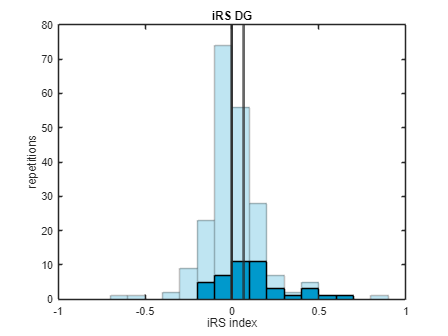


% [c_pvalues, c_alpha, h] = fwer_holmbonf(p_iRS, 0.05);
% [c_pvalues, c_alpha, h] = fwer_holmbonf(p_iRS_sig , 0.05);

% [p_iRS_sig h] = signrank(iRScasc)
% [p_iRS h] = signrank(iRScasc_S)

%Save figure
cd 'D:\Jazmin\MultichannelDataTanks\HIP\iRS';
saveas(gcf,'iRS_DG.pdf');
saveas(gcf,'iRS_DG.tif');
saveas(gcf,'iRS_DG.fig');
hold off

[h_kstest_iRS,p_kstest_iRS] = kstest(iRScasc_DG)

h_kstest_iRS = logical
   1


p_kstest_iRS = 7.1543e-27

[h_kstest_iRS_S,p_kstest_iRS_S] = kstest(iRScasc_S_DG)

h_kstest_iRS_S = logical
   1


p_kstest_iRS_S = 9.0401e-08

[h_ad_iRS,p_ad_iRS] = adtest(iRScasc_DG)

h_ad_iRS = logical
   1


p_ad_iRS = 5.0000e-04

[h_ad_iRS_S,p_ad_iRS_S] = adtest(iRScasc_S_DG)

h_ad_iRS_S = logical
   1


p_ad_iRS_S = 0.0205

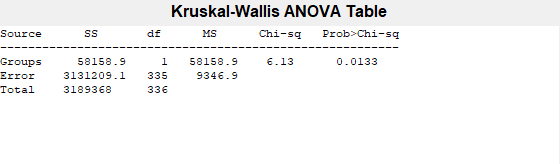

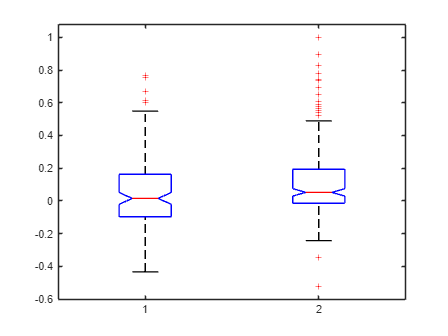

p_KW_iMM_Aud = 0.0133

iMM_CA1_Aud_Dis=[0 0 0 0 0 1 3 11 16 27 24 17 8 3 7 4 3 2 0 0];
iMM_CA1_Sig_Dis=[0 0 0 0 0 1 1 1 8 7 8 4 2 4 3 3 0 0];
iMM_DG_Aud_Dis = [0 0 0 0 2 0 1 1 12 51 59 35 16 9 6 9 4 3 2 1];
iMM_DG_Sig_Dis = [0 0 0 0 0 0 0 0 0 1 1 1 8 7 8 4 2 4 3 3];

iRS_CA1_Aud_Dis=[0 0 1 0 2 2 7 7 22 24 25 14 13 6 2 0 0 1 1 0];
iRS_CA1_Sig_Dis=[0 0 0 0 0 1 1 1 8 7 8 4 2 4 3 3 0 0];
iRS_DG_Aud_Dis=[0 0 0 1 1 0 2 9 23 74 56 28 7 2 5 1 1 0 1 0];
iRS_DG_Sig_Dis=[0 0 0 0 0 0 0 0 5 7 11 11 3 1 3 1 1 0 0 0];

iPE_CA1_Aud_Dis=[0 0 0 1 3 3 4 8 14 21 19 15 11 6 6 13 2 1 0 0];
iPE_CA1_Sig_Dis=[ 0 0 0 1 0 1 1 1 5 4 7 10 2 1 8 0 1 0 0];
iPE_DG_Aud_Dis = [0 0 0 1 1 4 1 4 12 52 53 21 23 14 10 8 4 1 0 2];
iPE_DG_Sig_Dis = [0 0 0 0 0 1 1 1 4 3 4 3 4 6 5 6 4 0 0 1];

Index_Matrix_Aud = NaN(214,6);
Index_Matrix_Aud([1:126],1) = iMMcasc_CA1;
Index_Matrix_Aud(:,2) = iMMcasc_DG;
Index_Matrix_Aud([1:126],3) = iPEcasc_CA1;
Index_Matrix_Aud(:,4) = iPEcasc_DG;
Index_Matrix_Aud([1:126],5) = iRScasc_CA1;
Index_Matrix_Aud(:,6) = iRScasc_DG;

Index_Matrix_Sig = NaN(44,6);
Index_Matrix_Sig([1:42],1) = iMMcasc_S_CA1;
Index_Matrix_Sig(:,2) = iMMcasc_S_DG;
Index_Matrix_Sig([1:42],3) = iPEcasc_S_CA1;
Index_Matrix_Sig(:,4) = iPEcasc_S_DG;
Index_Matrix_Sig([1:42],5) = iRScasc_S_CA1;
Index_Matrix_Sig(:,6) = iRScasc_S_DG;

p_KW_iMM_Aud = kruskalwallis(Index_Matrix_Aud(:,[1:2]))

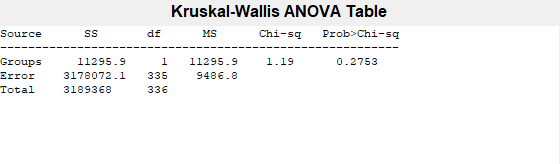

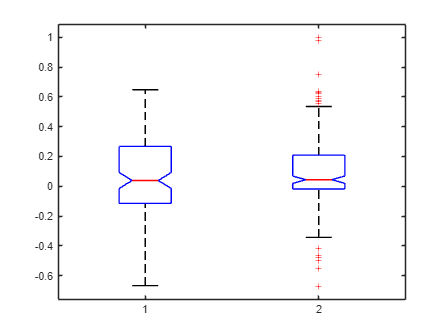

p_KW_iPE_Aud = 0.2753

p_KW_iPE_Aud = kruskalwallis(Index_Matrix_Aud(:,[3:4]))

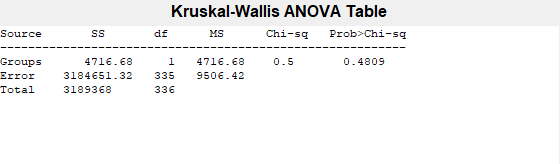

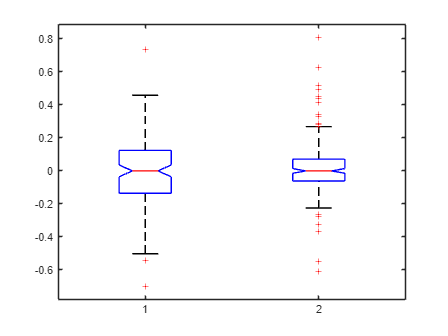

p_KW_iRS_Aud = 0.4809

p_KW_iRS_Aud = kruskalwallis(Index_Matrix_Aud(:,[5:6]))

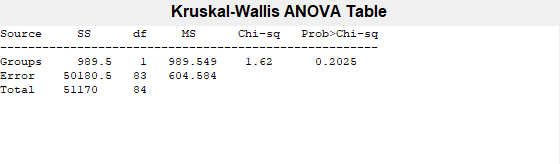

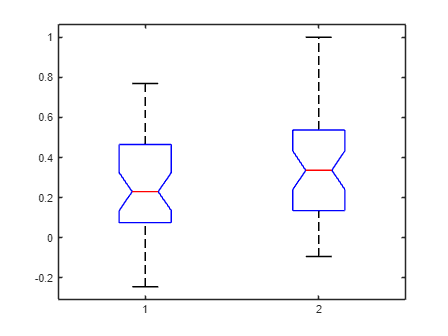

p_KW_iMM_Sig = 0.2025


p_KW_iMM_Sig = kruskalwallis(Index_Matrix_Sig(:,[1:2]))

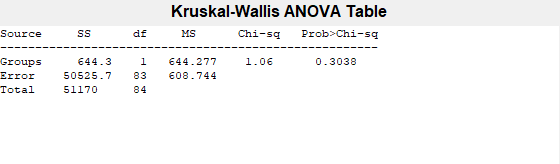

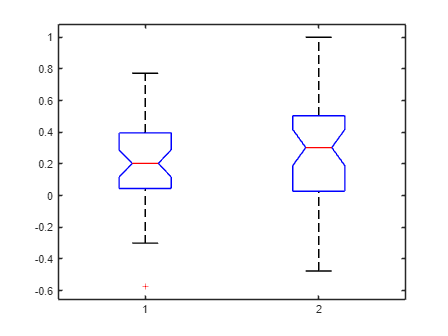

p_KW_iPE_Sig = 0.3038

p_KW_iPE_Sig = kruskalwallis(Index_Matrix_Sig(:,[3:4]))

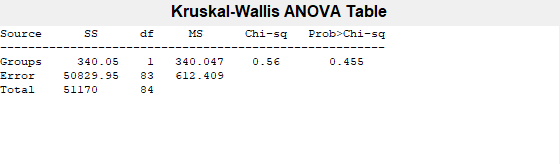

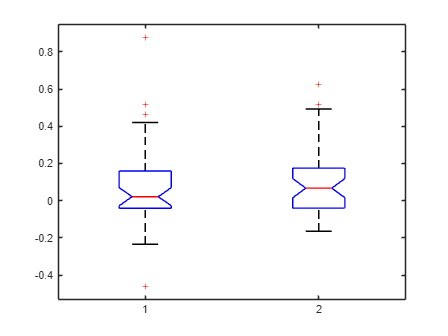

p_KW_iRS_Sig = 0.4550

p_KW_iRS_Sig = kruskalwallis(Index_Matrix_Sig(:,[5:6]))


Index_Matrix_Aud_CA1 = [iMMcasc_CA1 iPEcasc_CA1 iRScasc_CA1];
Index_Matrix_Aud_DG = [iMMcasc_DG iPEcasc_DG iRScasc_DG];
[h,p] = ttest2(Index_Matrix_Aud_CA1,Index_Matrix_Aud_DG)

h =      1     0     0


p =     0.0411    0.2758    0.2863



Index_Matrix_Sig_CA1 = [iMMcasc_S_CA1 iPEcasc_S_CA1  iRScasc_S_CA1];
Index_Matrix_Sig_DG = [iMMcasc_S_DG iPEcasc_S_DG  iRScasc_S_DG];
[h,p] = ttest2(Index_Matrix_Sig_CA1,Index_Matrix_Sig_DG)

h =      0     0     0


p =     0.1294    0.3429    0.6112



% [c_pvalues, c_alpha, h] = fwer_sidak(p_KW_Aud, 0.01);

pValues = [p_iMM_DG; p_iMM_sig_DG; p_iMM_CA1; p_iMM_sig_CA1; p_iPE_DG; p_iPE_sig_DG; p_iPE_CA1; p_iPE_sig_CA1; p_iRS_DG; p_iRS_sig_DG; p_iRS_CA1; p_iRS_sig_CA1];

m = length(pValues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
correctedPValues = pValues * m;

% Display results
table(pValues, correctedPValues, 'VariableNames', {'pValue', 'Bonfe_Cor_pValue'})

ans = 12×2 table
      pValue      Bonfe_Cor_pValue
    __________    ________________

    6.8304e-12       8.1964e-11   
    1.3659e-11        1.639e-10   
     0.0067955         0.081546   
    9.3531e-09       1.1224e-07   
    3.0084e-09         3.61e-08   
    3.0922e-06       3.7107e-05   
     0.0073346         0.088015   
    2.9804e-05       0.00035765   
        0.2628           3.1536   
     0.0010364         0.012437   
       0.61795           7.4154   
      0.031427          0.37712   



aov_Aud = anova(Index_Matrix_Aud)

aov_Aud = 1-way anova, constrained (Type III) sums of squares.

Y ~ 1 + Factor1

               SumOfSquares     DF     MeanSquares      F         pValue  
               ____________    ____    ___________    ______    __________

    Factor1       2.0878          5      0.41756      7.9694    2.2306e-07
    Error         52.658       1005     0.052396                          
    Total         54.746       1010                                       


  Properties, Methods



multcompare(aov_Aud, "Alpha",0.05,"CriticalValueType","bonferroni")

ans = 15×6 table
    Group1    Group2    MeanDifference    MeanDifferenceLower    MeanDifferenceUpper      pValue  
    ______    ______    ______________    ___________________    ___________________    __________

      1         2          -0.054291            -0.13012              0.021534             0.53093
      1         3         -0.0098445           -0.094696              0.075006                   1
      1         4          -0.041602            -0.11743              0.034224                   1
      1         5           0.070066           -0.014785               0.15492             0.22937
      1         6           0.047532           -0.028294               0.12336             0.98138
      2         3           0.044447           -0.031379               0.12027       


aov_Sig = anova(Index_Matrix_Sig)

aov_Sig = 1-way anova, constrained (Type III) sums of squares.

Y ~ 1 + Factor1

               SumOfSquares    DF     MeanSquares      F        pValue  
               ____________    ___    ___________    _____    __________

    Factor1       2.4492         5      0.48984      7.577    1.2096e-06
    Error         16.098       249     0.064649                         
    Total         18.547       254                                      


  Properties, Methods



multcompare(aov_Sig, "Alpha",0.05,"CriticalValueType","bonferroni")

ans = 15×6 table
    Group1    Group2    MeanDifference    MeanDifferenceLower    MeanDifferenceUpper      pValue  
    ______    ______    ______________    ___________________    ___________________    __________

      1         2         -0.083917               -0.2474             0.079568                   1
      1         3          0.079104              -0.08534              0.24355                   1
      1         4          0.018552              -0.14493              0.18204                   1
      1         5           0.19594              0.031496              0.36038           0.0073848
      1         6           0.17258             0.0090906              0.33606            0.029484
      2         3           0.16302           -0.00046411              0.32651       

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Combine the two columns and omit NaNs
all_values_SI_CA1  = [Table_CA1_Aud.Table_CA1_Aud.SI1;Table_CA1_Aud.Table_CA1_Aud.SI2];
all_values_SI_CA1  = all_values_SI_CA1 (~isnan(all_values_SI_CA1 ));  % Remove NaNs
median_ALL_SI_CA1 = median(all_values_SI_CA1)

median_ALL_SI_CA1 = 0.0125

p = signrank(all_values_SI_CA1, 0)

p = 0.0941


% Keep only positive values
positive_values_SI_CA1 = all_values_SI_CA1 (all_values_SI_CA1  > 0);

% Compute the mean of the positive values

SI_Mean_pos_CA1 = mean(positive_values_SI_CA1)

SI_Mean_pos_CA1 = 0.2003

err = std(positive_values_SI_CA1) / sqrt((size(positive_values_SI_CA1,1))*2)

err = 0.0158

[h p_SI_CA1] = ttest(positive_values_SI_CA1) 

h = 1

p_SI_CA1 = 4.2691e-13


% Combine the two columns and omit NaNs
all_values_SI_S_CA1  = [Table_CA1_Sig.Table_CA1_Sig.SI1; Table_CA1_Sig.Table_CA1_Sig.SI2];
all_values_SI_S_CA1  = all_values_SI_S_CA1 (~isnan(all_values_SI_S_CA1 ));  % Remove NaNs
median_ALL_SI_S_CA1 = median(all_values_SI_S_CA1)

median_ALL_SI_S_CA1 = 0.2072

p = signrank(all_values_SI_S_CA1, 0)

p = 2.6715e-07


% Keep only positive values
positive_values_SI_S_CA1 = all_values_SI_S_CA1 (all_values_SI_S_CA1  > 0);

% Compute the mean of the positive values

SI_Mean_S_pos_CA1 = mean(positive_values_SI_S_CA1)

SI_Mean_S_pos_CA1 = 0.2878

err_S = std(positive_values_SI_S_CA1) / sqrt((size(positive_values_SI_S_CA1,1))*2)

err_S = 0.0249

[h p_SI_S_CA1] = ttest(positive_values_SI_S_CA1) 

h = 1

p_SI_S_CA1 = 6.5454e-10


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Combine the two columns and omit NaNs
all_values_SI_DG  = [Table_DG_Aud.Table_DG_Aud.SI1;Table_DG_Aud.Table_DG_Aud.SI2];
all_values_SI_DG  = all_values_SI_DG (~isnan(all_values_SI_DG ));  % Remove NaNs
median_ALL_SI_DG = median(all_values_SI_DG)

median_ALL_SI_DG = 0.0479

p = signrank(all_values_SI_DG, 0)

p = 2.9869e-12


% Keep only positive values
positive_values_SI_DG = all_values_SI_DG (all_values_SI_DG  > 0);

% Compute the mean of the positive values

SI_Mean_pos_DG = mean(positive_values_SI_DG)

SI_Mean_pos_DG = 0.1894

err = std(positive_values_SI_DG) / sqrt((size(positive_values_SI_DG,1))*2)

err = 0.0130

[h p_SI_DG] = ttest(positive_values_SI_DG) 

h = 1

p_SI_DG = 4.9821e-19


% Combine the two columns and omit NaNs
all_values_SI_S_DG  = [Table_DG_Sig.Table_DG_Sig.SI1;Table_DG_Sig.Table_DG_Sig.SI2];
all_values_SI_S_DG  = all_values_SI_S_DG (~isnan(all_values_SI_S_DG ));  % Remove NaNs
median_ALL_SI_S_DG = median(all_values_SI_S_DG)

median_ALL_SI_S_DG = 0.3439

p = signrank(all_values_SI_S_DG, 0)

p = 1.4134e-08


% Keep only positive values
positive_values_SI_S_DG = all_values_SI_S_DG (all_values_SI_S_DG  > 0);

% Compute the mean of the positive values

SI_Mean_S_pos_DG = mean(positive_values_SI_S_DG)

SI_Mean_S_pos_DG = 0.3573

err_S = std(positive_values_SI_S_DG) / sqrt((size(positive_values_SI_S_DG,1))*2)

err_S = 0.0275

[h p_SI_S_DG] = ttest(positive_values_SI_S_DG) 

h = 1

p_SI_S_DG = 1.7255e-11


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Combine the two columns and omit NaNs
all_values_CSI_CA1  = [Table_CA1_Aud.Table_CA1_Aud.CSI];
all_values_CSI_CA1  = all_values_CSI_CA1 (~isnan(all_values_CSI_CA1 ));  % Remove NaNs
median_ALL_CSI_CA1 = median(all_values_CSI_CA1)

median_ALL_CSI_CA1 = 0.0188

p = signrank(all_values_CSI_CA1, 0)

p = 0.0696


% Keep only positive values
positive_values_CSI_CA1 = all_values_CSI_CA1 (all_values_CSI_CA1  > 0);

% Compute the mean of the positive values

CSI_Mean_pos_CA1 = mean(positive_values_CSI_CA1)

CSI_Mean_pos_CA1 = 0.1494

err_S = std(positive_values_CSI_CA1) / sqrt((size(positive_values_CSI_CA1,1))*2)

err_S = 0.0184

[h p_CSI_CA1] = ttest(positive_values_CSI_CA1) 

h = 1

p_CSI_CA1 = 1.6052e-06


% Combine the two columns and omit NaNs
all_values_CSI_S_CA1  = [Table_CA1_Sig.Table_CA1_Sig.CSI];
all_values_CSI_S_CA1  = all_values_CSI_S_CA1 (~isnan(all_values_CSI_S_CA1 ));  % Remove NaNs
median_ALL_CSI_S_CA1 = median(all_values_CSI_S_CA1)

median_ALL_CSI_S_CA1 = 0.2128

p = signrank(all_values_CSI_S_CA1, 0)

p = 1.0642e-04


% Keep only positive values
positive_values_CSI_S_CA1 = all_values_CSI_S_CA1 (all_values_CSI_S_CA1  > 0);

% Compute the mean of the positive values

CSI_Mean_S_pos_CA1 = mean(positive_values_CSI_S_CA1)

CSI_Mean_S_pos_CA1 = 0.2701

err_S = std(positive_values_CSI_S_CA1) / sqrt((size(positive_values_CSI_S_CA1,1))*2)

err_S = 0.0297

[h p_CSI_S_CA1] = ttest(positive_values_CSI_S_CA1) 

h = 1

p_CSI_S_CA1 = 3.6816e-06


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Combine the two columns and omit NaNs
all_values_CSI_DG  = [Table_DG_Aud.Table_DG_Aud.CSI];
all_values_CSI_DG  = all_values_CSI_DG (~isnan(all_values_CSI_DG ));  % Remove NaNs
median_ALL_CSI_DG = median(all_values_CSI_DG)

median_ALL_CSI_DG = 0.0466

p = signrank(all_values_CSI_DG, 0)

p = 2.8605e-10


% Keep only positive values
positive_values_CSI_DG = all_values_CSI_DG (all_values_CSI_DG  > 0);

% Compute the mean of the positive values

CSI_Mean_pos_DG = mean(positive_values_CSI_DG)

CSI_Mean_pos_DG = 0.1637

err = std(positive_values_CSI_DG) / sqrt((size(positive_values_CSI_DG,1))*2)

err = 0.0151

[h p_CSI_DG] = ttest(positive_values_CSI_DG) 

h = 1

p_CSI_DG = 5.3723e-11


% Combine the two columns and omit NaNs
all_values_CSI_S_DG  = [Table_DG_Sig.Table_DG_Sig.CSI];
all_values_CSI_S_DG  = all_values_CSI_S_DG (~isnan(all_values_CSI_S_DG ));  % Remove NaNs
median_ALL_CSI_S_DG = median(all_values_CSI_S_DG)

median_ALL_CSI_S_DG = 0.2714

p = signrank(all_values_CSI_S_DG, 0)

p = 4.0100e-05


% Keep only positive values
positive_values_CSI_S_DG = all_values_CSI_S_DG (all_values_CSI_S_DG  > 0);

% Compute the mean of the positive values

CSI_Mean_S_pos_DG = mean(positive_values_CSI_S_DG)

CSI_Mean_S_pos_DG = 0.3308

err_S = std(positive_values_CSI_S_DG) / sqrt((size(positive_values_CSI_S_DG,1))*2)

err_S = 0.0342

[h p_CSI_S_DG] = ttest(positive_values_CSI_S_DG) 

h = 1

p_CSI_S_DG = 9.0347e-07


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Combine the two columns and omit NaNs
all_values_iMM_CA1 = cat(1,Table_CA1_Aud.Table_CA1_Aud.iMM1ca,Table_CA1_Aud.Table_CA1_Aud.iMM2cd);
all_values_iMM_CA1  = all_values_iMM_CA1 (~isnan(all_values_iMM_CA1 ));  % Remove NaNs
median_ALL_iMM_CA1 = median(all_values_iMM_CA1)

median_ALL_iMM_CA1 = 0.0156

p = signrank(all_values_iMM_CA1, 0)

p = 0.0703


% Keep only positive values
positive_values_iMM_CA1 = all_values_iMM_CA1 (all_values_iMM_CA1  > 0);

% Compute the mean of the positive values

iMM_Mean_pos_CA1 = mean(positive_values_iMM_CA1)

iMM_Mean_pos_CA1 = 0.2264

err = std(positive_values_iMM_CA1) / sqrt((size(positive_values_iMM_CA1,1))*2)

err = 0.0176

[h p_iMM_CA1] = ttest(positive_values_iMM_CA1) 

h = 1

p_iMM_CA1 = 2.5350e-13


% Combine the two columns and omit NaNs
all_values_iMM_S_CA1  = cat(1,Table_CA1_Sig.Table_CA1_Sig.iMM1ca,Table_CA1_Sig.Table_CA1_Sig.iMM2cd);
all_values_iMM_S_CA1  = all_values_iMM_S_CA1 (~isnan(all_values_iMM_S_CA1 ));  % Remove NaNs
median_ALL_iMM_S_CA1 = median(all_values_iMM_S_CA1)

median_ALL_iMM_S_CA1 = 0.2299

p = signrank(all_values_iMM_S_CA1, 0)

p = 2.8553e-07


% Keep only positive values
positive_values_iMM_S_CA1 = all_values_iMM_S_CA1 (all_values_iMM_S_CA1  > 0);

% Compute the mean of the positive values

iMM_Mean_S_pos_CA1 = mean(positive_values_iMM_S_CA1)

iMM_Mean_S_pos_CA1 = 0.3079

err = std(positive_values_iMM_S_CA1) / sqrt((size(positive_values_iMM_S_CA1,1))*2)

err = 0.0255

[h p_iMM_S_CA1] = ttest(positive_values_iMM_S_CA1) 

h = 1

p_iMM_S_CA1 = 2.2617e-10


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Combine the two columns and omit NaNs
all_values_iMM_DG  = cat(1,Table_DG_Aud.Table_DG_Aud.iMM1ca,Table_DG_Aud.Table_DG_Aud.iMM2cd);
all_values_iMM_DG  = all_values_iMM_DG (~isnan(all_values_iMM_DG ));  % Remove NaNs
median_ALL_iMM_DG = median(all_values_iMM_DG)

median_ALL_iMM_DG = 0.0525

p = signrank(all_values_iMM_DG, 0)

p = 5.2686e-12


% Keep only positive values
positive_values_iMM_DG = all_values_iMM_DG (all_values_iMM_DG  > 0);

% Compute the mean of the positive values

iMM_Mean_pos_DG = mean(positive_values_iMM_DG)

iMM_Mean_pos_DG = 0.2030

err = std(positive_values_iMM_DG) / sqrt((size(positive_values_iMM_DG,1))*2)

err = 0.0128

[h p_iMM_DG] = ttest(positive_values_iMM_DG) 

h = 1

p_iMM_DG = 2.3390e-21


% Combine the two columns and omit NaNs
all_values_iMM_S_DG  = cat(1,Table_DG_Sig.Table_DG_Sig.iMM1ca,Table_DG_Sig.Table_DG_Sig.iMM2cd);
all_values_iMM_S_DG  = all_values_iMM_S_DG (~isnan(all_values_iMM_S_DG ));  % Remove NaNs
median_ALL_iMM_S_DG = median(all_values_iMM_S_DG)

median_ALL_iMM_S_DG = 0.3366

p = signrank(all_values_iMM_S_DG, 0)

p = 1.9673e-08


% Keep only positive values
positive_values_iMM_S_DG = all_values_iMM_S_DG (all_values_iMM_S_DG  > 0);

% Compute the mean of the positive values

iMM_Mean_S_pos_DG = mean(positive_values_iMM_S_DG)

iMM_Mean_S_pos_DG = 0.3790

err = std(positive_values_iMM_S_DG) / sqrt((size(positive_values_iMM_S_DG,1))*2)

err = 0.0271

[h p_iMM_S_DG] = ttest(positive_values_iMM_S_DG) 

h = 1

p_iMM_S_DG = 2.6348e-12


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Combine the two columns and omit NaNs
all_values_iPE_CA1 = cat(1,Table_CA1_Aud.Table_CA1_Aud.iPE1ca,Table_CA1_Aud.Table_CA1_Aud.iPE2cd);
all_values_iPE_CA1  = all_values_iPE_CA1 (~isnan(all_values_iPE_CA1 ));  % Remove NaNs
median_ALL_iPE_CA1 = median(all_values_iPE_CA1)

median_ALL_iPE_CA1 = 0.0386

p = signrank(all_values_iPE_CA1, 0)

p = 0.0137


% Keep only positive values
positive_values_iPE_CA1 = all_values_iPE_CA1 (all_values_iPE_CA1  > 0);

% Compute the mean of the positive values

iPE_Mean_pos_CA1 = mean(positive_values_iPE_CA1)

iPE_Mean_pos_CA1 = 0.2630

err = std(positive_values_iPE_CA1) / sqrt((size(positive_values_iPE_CA1,1))*2)

err = 0.0161

[h p_iPE_CA1] = ttest(positive_values_iPE_CA1) 

h = 1

p_iPE_CA1 = 6.4447e-18


% Combine the two columns and omit NaNs
all_values_iPE_S_CA1  = cat(1,Table_CA1_Sig.Table_CA1_Sig.iPE1ca,Table_CA1_Sig.Table_CA1_Sig.iPE2cd);
all_values_iPE_S_CA1  = all_values_iPE_S_CA1 (~isnan(all_values_iPE_S_CA1 ));  % Remove NaNs
median_ALL_iPE_S_CA1 = median(all_values_iPE_S_CA1)

median_ALL_iPE_S_CA1 = 0.2030

p = signrank(all_values_iPE_S_CA1, 0)

p = 4.9614e-05


% Keep only positive values
positive_values_iPE_S_CA1 = all_values_iPE_S_CA1 (all_values_iPE_S_CA1  > 0);

% Compute the mean of the positive values

iPE_Mean_S_pos_CA1 = mean(positive_values_iPE_S_CA1)

iPE_Mean_S_pos_CA1 = 0.2955

err = std(positive_values_iPE_S_CA1) / sqrt((size(positive_values_iPE_S_CA1,1))*2)

err = 0.0239

[h p_iPE_S_CA1] = ttest(positive_values_iPE_S_CA1) 

h = 1

p_iPE_S_CA1 = 5.7076e-10


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Combine the two columns and omit NaNs
all_values_iPE_DG  = cat(1,Table_DG_Aud.Table_DG_Aud.iPE1ca,Table_DG_Aud.Table_DG_Aud.iPE2cd);
all_values_iPE_DG  = all_values_iPE_DG (~isnan(all_values_iPE_DG ));  % Remove NaNs
median_ALL_iPE_DG = median(all_values_iPE_DG)

median_ALL_iPE_DG = 0.0438

p = signrank(all_values_iPE_DG, 0)

p = 7.3794e-09


% Keep only positive values
positive_values_iPE_DG = all_values_iPE_DG (all_values_iPE_DG  > 0);

% Compute the mean of the positive values

iPE_Mean_pos_DG = mean(positive_values_iPE_DG)

iPE_Mean_pos_DG = 0.2148

err = std(positive_values_iPE_DG) / sqrt((size(positive_values_iPE_DG,1))*2)

err = 0.0123

[h p_iPE_DG] = ttest(positive_values_iPE_DG) 

h = 1

p_iPE_DG = 7.5029e-24


% Combine the two columns and omit NaNs
all_values_iPE_S_DG  = cat(1,Table_DG_Sig.Table_DG_Sig.iPE1ca,Table_DG_Sig.Table_DG_Sig.iPE2cd);
all_values_iPE_S_DG  = all_values_iPE_S_DG (~isnan(all_values_iPE_S_DG ));  % Remove NaNs
median_ALL_iPE_S_DG = median(all_values_iPE_S_DG)

median_ALL_iPE_S_DG = 0.3032

p = signrank(all_values_iPE_S_DG, 0)

p = 2.3764e-05


% Keep only positive values
positive_values_iPE_S_DG = all_values_iPE_S_DG (all_values_iPE_S_DG  > 0);

% Compute the mean of the positive values

iPE_Mean_S_pos_DG = mean(positive_values_iPE_S_DG)

iPE_Mean_S_pos_DG = 0.3884

err = std(positive_values_iPE_S_DG) / sqrt((size(positive_values_iPE_S_DG,1))*2)

err = 0.0261

[h p_iPE_S_DG] = ttest(positive_values_iPE_S_DG) 

h = 1

p_iPE_S_DG = 6.6031e-12

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Combine the two columns and omit NaNs
all_values_iRS_CA1 = cat(1,Table_CA1_Aud.Table_CA1_Aud.iRS1ca,Table_CA1_Aud.Table_CA1_Aud.iRS2cd);
all_values_iRS_CA1  = all_values_iRS_CA1 (~isnan(all_values_iRS_CA1 ));  % Remove NaNs
median_ALL_iRS_CA1 = median(all_values_iRS_CA1)

median_ALL_iRS_CA1 = -0.0014

p = signrank(all_values_iRS_CA1, 0)

p = 0.6834


% Keep only positive values
positive_values_iRS_CA1 = all_values_iRS_CA1 (all_values_iRS_CA1  > 0);

% Compute the mean of the positive values

iRS_Mean_pos_CA1 = mean(positive_values_iRS_CA1)

iRS_Mean_pos_CA1 = 0.1615

err = std(positive_values_iRS_CA1) / sqrt((size(positive_values_iRS_CA1,1))*2)

err = 0.0128

[h p_iRS_CA1] = ttest(positive_values_iRS_CA1) 

h = 1

p_iRS_CA1 = 1.1862e-12


% Combine the two columns and omit NaNs
all_values_iRS_S_CA1  = cat(1,Table_CA1_Sig.Table_CA1_Sig.iRS1ca,Table_CA1_Sig.Table_CA1_Sig.iRS2cd);
all_values_iRS_S_CA1  = all_values_iRS_S_CA1 (~isnan(all_values_iRS_S_CA1 ));  % Remove NaNs
median_ALL_iRS_S_CA1 = median(all_values_iRS_S_CA1)

median_ALL_iRS_S_CA1 = 0.0211

p = signrank(all_values_iRS_S_CA1, 0)

p = 0.0708


% Keep only positive values
positive_values_iRS_S_CA1 = all_values_iRS_S_CA1 (all_values_iRS_S_CA1  > 0);

% Compute the mean of the positive values

iRS_Mean_S_pos_CA1 = mean(positive_values_iRS_S_CA1)

iRS_Mean_S_pos_CA1 = 0.2103

err = std(positive_values_iRS_S_CA1) / sqrt((size(positive_values_iRS_S_CA1,1))*2)

err = 0.0298

[h p_iRS_S_CA1] = ttest(positive_values_iRS_S_CA1) 

h = 1

p_iRS_S_CA1 = 4.8400e-05


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Combine the two columns and omit NaNs
all_values_iRS_DG  = cat(1,Table_DG_Aud.Table_DG_Aud.iRS1ca,Table_DG_Aud.Table_DG_Aud.iRS2cd);
all_values_iRS_DG  = all_values_iRS_DG (~isnan(all_values_iRS_DG ));  % Remove NaNs
median_ALL_iRS_DG = median(all_values_iRS_DG)

median_ALL_iRS_DG = -0.0017

p = signrank(all_values_iRS_DG, 0)

p = 0.7573


% Keep only positive values
positive_values_iRS_DG = all_values_iRS_DG (all_values_iRS_DG  > 0);

% Compute the mean of the positive values

iRS_Mean_pos_DG = mean(positive_values_iRS_DG)

iRS_Mean_pos_DG = 0.1245

err = std(positive_values_iRS_DG) / sqrt((size(positive_values_iRS_DG,1))*2)

err = 0.0103

[h p_iRS_DG] = ttest(positive_values_iRS_DG) 

h = 1

p_iRS_DG = 1.7647e-13


% Combine the two columns and omit NaNs
all_values_iRS_S_DG  = cat(1,Table_DG_Sig.Table_DG_Sig.iRS1ca,Table_DG_Sig.Table_DG_Sig.iRS2cd);
all_values_iRS_S_DG  = all_values_iRS_S_DG (~isnan(all_values_iRS_S_DG ));  % Remove NaNs
median_ALL_iRS_S_DG = median(all_values_iRS_S_DG)

median_ALL_iRS_S_DG = 0.0671

p = signrank(all_values_iRS_S_DG, 0)

p = 0.0025


% Keep only positive values
positive_values_iRS_S_DG = all_values_iRS_S_DG (all_values_iRS_S_DG  > 0);

% Compute the mean of the positive values

iRS_Mean_S_pos_DG = mean(positive_values_iRS_S_DG)

iRS_Mean_S_pos_DG = 0.1865

err = std(positive_values_iRS_S_DG) / sqrt((size(positive_values_iRS_S_DG,1))*2)

err = 0.0214

[h p_iRS_S_DG] = ttest(positive_values_iRS_S_DG) 

h = 1

p_iRS_S_DG = 9.8524e-07

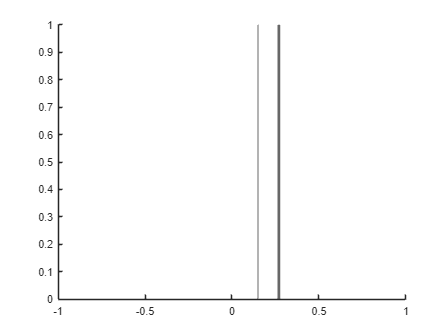

figure
xlim([-1 1]);
hold on
xline(CSI_Mean_pos_CA1,'LineWidth',1);
xline(CSI_Mean_S_pos_CA1,'LineWidth',2.5);
%Save figure
cd 'D:\Jazmin\MultichannelDataTanks\HIP\positive media';
saveas(gcf,'CSI_CA1.pdf');
hold off

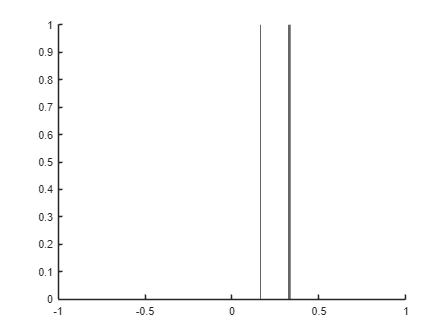


figure
xlim([-1 1]);
hold on
xline(CSI_Mean_pos_DG,'LineWidth',1);
xline(CSI_Mean_S_pos_DG,'LineWidth',2.5);
%Save figure
cd 'D:\Jazmin\MultichannelDataTanks\HIP\positive media';
saveas(gcf,'CSI_DG.pdf');
hold off

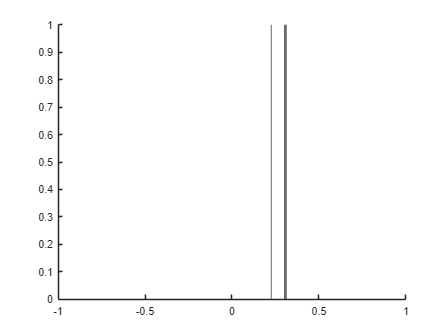


figure
xlim([-1 1]);
hold on
xline(iMM_Mean_pos_CA1,'LineWidth',1);
xline(iMM_Mean_S_pos_CA1,'LineWidth',2.5);
%Save figure
cd 'D:\Jazmin\MultichannelDataTanks\HIP\positive media';
saveas(gcf,'iMM_CA1.pdf');
hold off

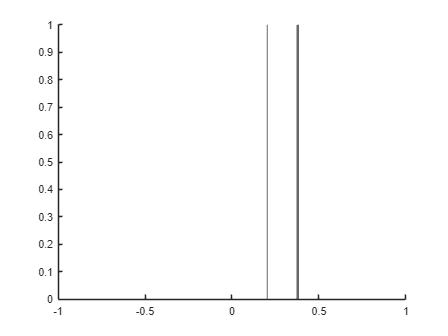


figure
xlim([-1 1]);
hold on
xline(iMM_Mean_pos_DG,'LineWidth',1);
xline(iMM_Mean_S_pos_DG,'LineWidth',2.5);
%Save figure
cd 'D:\Jazmin\MultichannelDataTanks\HIP\positive media';
saveas(gcf,'iMM_DG.pdf');
hold off

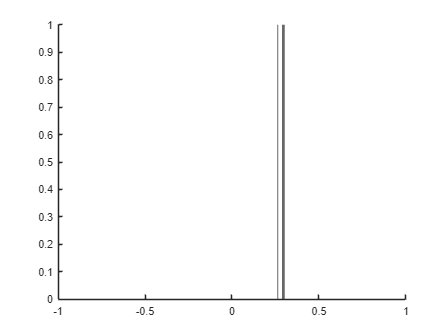


figure
xlim([-1 1]);
hold on
xline(iPE_Mean_pos_CA1,'LineWidth',1);
xline(iPE_Mean_S_pos_CA1,'LineWidth',2.5);
%Save figure
cd 'D:\Jazmin\MultichannelDataTanks\HIP\positive media';
saveas(gcf,'iPE_CA1.pdf');
hold off

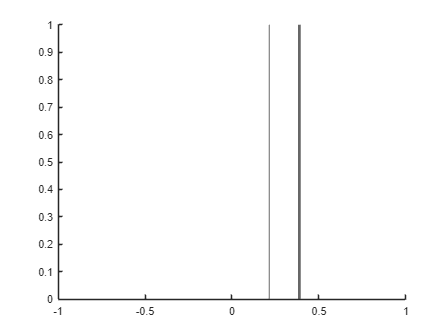


figure
xlim([-1 1]);
hold on
xline(iPE_Mean_pos_DG,'LineWidth',1);
xline(iPE_Mean_S_pos_DG,'LineWidth',2.5);
%Save figure
cd 'D:\Jazmin\MultichannelDataTanks\HIP\positive media';
saveas(gcf,'iPE_DG.pdf');
hold off

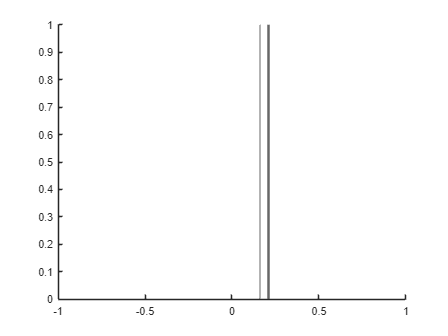


figure
xlim([-1 1]);
hold on
xline(iRS_Mean_pos_CA1,'LineWidth',1);
xline(iRS_Mean_S_pos_CA1,'LineWidth',2.5);
%Save figure
cd 'D:\Jazmin\MultichannelDataTanks\HIP\positive media';
saveas(gcf,'iRS_CA1.pdf');
hold off

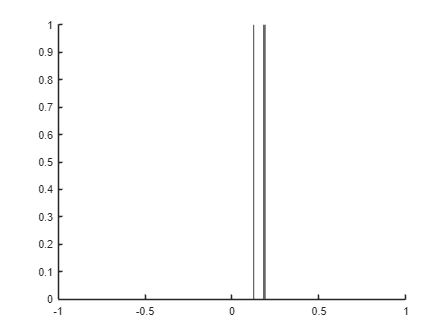


figure
xlim([-1 1]);
hold on
xline(iRS_Mean_pos_DG,'LineWidth',1);
xline(iRS_Mean_S_pos_DG,'LineWidth',2.5);
%Save figure
cd 'D:\Jazmin\MultichannelDataTanks\HIP\positive media';
saveas(gcf,'iRS_DG.pdf');
hold off